# FILTRO DE KALMAN PARA ESTIMAR UN PARÁMETRO DESCONOCIDO

En este ejemplo se estima un parámetro constante "a" de un sistema:

      
$$y(k)=a*u(k)+v(k)$$


donde:

  - $u(k)$: entrada conocida

  - $y(k)$: salida medida

  - $a$ : parámetro desconocido (constante)

  - $v(k)$: ruido de medición

El filtro de Kalman se utiliza tratando el parámetro como un estado:


$$a(k+1)=a(k)+w(k)$$
      

donde $w(k)$ es el ruido del proceso

% CONFIGURACIÓN DE LA SIMULACIÓN
N = 100;            % Número de muestras
sigma_v = 0.5;      % Desviación estándar del ruido de medición
sigma_w = 1e-3;     % Desviación estándar del ruido de proceso
% Valor real del parámetro
a_real = 2.75;

Se realiza la simulacion para obtener los datos del problema

k = 1:N;
u = sin(0.1*k) + 0.2*randn(1,N);      % Entrada conocida
v = sigma_v * randn(1,N);             % Ruido de medición
y = a_real * u + v;                   % Salida medida

Inicializacion de los parametros del filtro de Kalman

% Estado: x = a
x_est = 0;            % Estimación inicial del parámetro
P = 10;               % Covarianza inicial (alta incertidumbre)
F = 1;                % Matriz de transicion 

Q = sigma_w^2;        % Covarianza del ruido de proceso
R = sigma_v^2;        % Covarianza del ruido de medición

% Almacenamiento de resultados
x_t = zeros(1,N);
P_t = zeros(1,N);


FILTRO DE KALMAN

%% iteraciones sobre el numero de muestras disponible
for i = 1:N
    
    %---------------------------------------------------------------
    % 1. PREDICCIÓN
    % Modelo del estado: x(k+1) = F * x(k)
    %---------------------------------------------------------------
    x_pred = F * x_est;
    P_pred = F*P*F' + Q;
    
    %---------------------------------------------------------------
    % 2. ACTUALIZACIÓN
    % Modelo de medición: y(k) = H*x + v
    % H = u(k)
    %---------------------------------------------------------------
    H = u(i);
    % Innovación (error entre medición y predicción)
    innov = y(i) - H * x_pred;
    
    % Ganancia de Kalman
    S = H*P*H' + R;
    K = P_pred * H' / S;
    
    % Corrección de la estimación
    x_est = x_pred + K * innov;
    
    % Actualización de la covarianza
    P = (1 - K * H) * P_pred;
    
    % Guardar resultados
    x_t(i) = x_est;
    P_t(i) = P;
end

Resultados y evaluacion

fprintf('Valor real del parámetro: %.4f\n', a_real);

Valor real del parámetro: 2.7500


fprintf('Estimación final:         %.4f\n', x_est);

Estimación final:         2.7964


fprintf('Error absoluto final:     %.4f\n', abs(a_real - x_est));

Error absoluto final:     0.0464


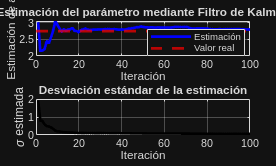


% GRÁFICAS
figure;

% Evolución de la estimación
subplot(2,1,1);
plot(k, x_t, 'b', 'LineWidth', 2); hold on;
yline(a_real, 'r--', 'LineWidth', 2);
grid on;
xlabel('Iteración');
ylabel('Estimación de a');
title('Estimación del parámetro mediante Filtro de Kalman');
legend('Estimación', 'Valor real', 'Location', 'best');

% Evolución de la incertidumbre
subplot(2,1,2);
plot(k, sqrt(P_t), 'k', 'LineWidth', 2);
grid on;
xlabel('Iteración');
ylabel('\sigma estimada');
title('Desviación estándar de la estimación');

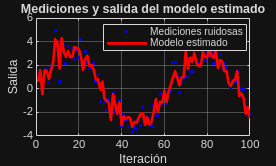


% Comparacion real vs estimacion
y_est = x_est * u;

figure;
plot(k, y, 'b.');
hold on;
plot(k, y_est, 'r', 'LineWidth', 2);
grid on;
xlabel('Iteración');
ylabel('Salida');
title('Mediciones y salida del modelo estimado');
legend('Mediciones ruidosas', 'Modelo estimado', 'Location', 'best');